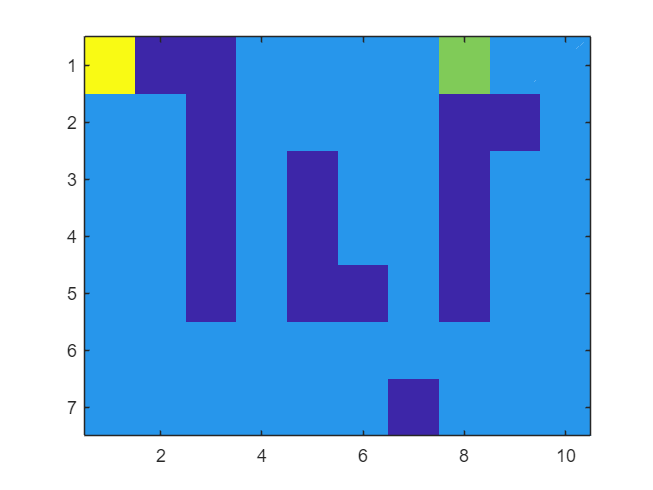

map=[3 0 0 1 1 1 1 2 1 1
     1 1 0 1 1 1 1 0 0 1
     1 1 0 1 0 1 1 0 1 1
     1 1 0 1 0 1 1 0 1 1
     1 1 0 1 0 0 1 0 1 1
     1 1 1 1 1 1 1 1 1 1
     1 1 1 1 1 1 0 1 1 1];

imagesc(map)

completed = false;
numerical_map=-ones(7,10);
numerical_map(find(map==3))=0;
current_step=0;

while (completed == false && current_step<30)
    [current_positions_r,current_positions_c] = find(numerical_map==current_step);
    current_step=current_step+1;
    current_positions=[current_positions_r,current_positions_c];
    for i=1:length(current_positions_r+1)
        up=current_positions(i,:)+[-1,0];
        if(up(1)>0 && up(1)<=7 && up(2)>0 && up(2)<=10)
            if(map(up(1),up(2)) ~= 0 && numerical_map(up(1),up(2)) ==-1)
                 numerical_map(up(1),up(2)) = current_step;
            end
        end
        right=current_positions(i,:)+[0,1];
        if(right(1)>0 && right(1)<=7 && right(2)>0 && right(2)<=10)
            if(map(right(1),right(2)) ~= 0 && numerical_map(right(1),right(2)) == -1)
                 numerical_map(right(1),right(2)) = current_step;
            end
        end
        down=current_positions(i,:)+[1,0];
        if(down(1)>0 && down(1)<=7 && down(2)>0 && down(2)<=10)
            if(map(down(1),down(2)) ~= 0 && numerical_map(down(1),down(2)) ==-1)
                 numerical_map(down(1),down(2)) = current_step;
            end
        end
        left=current_positions(i,:)+[0,-1];
        if(left(1)>0 && left(1)<=7 && left(2)>0 && left(2)<=10)
            if(map(left(1),left(2)) ~= 0 && numerical_map(left(1),left(2)) ==-1)
                 numerical_map(left(1),left(2)) = current_step;
            end
        end
    end
end
numerical_map

numerical_map =      0    -1    -1    13    14    15    16    17    18    19
     1     2    -1    12    13    14    15    -1    -1    18
     2     3    -1    11    -1    15    14    -1    16    17
     3     4    -1    10    -1    14    13    -1    15    16
     4     5    -1     9    -1    -1    12    -1    14    15
     5     6     7     8     9    10    11    12    13    14
     6     7     8     9    10    11    -1    13    14    15


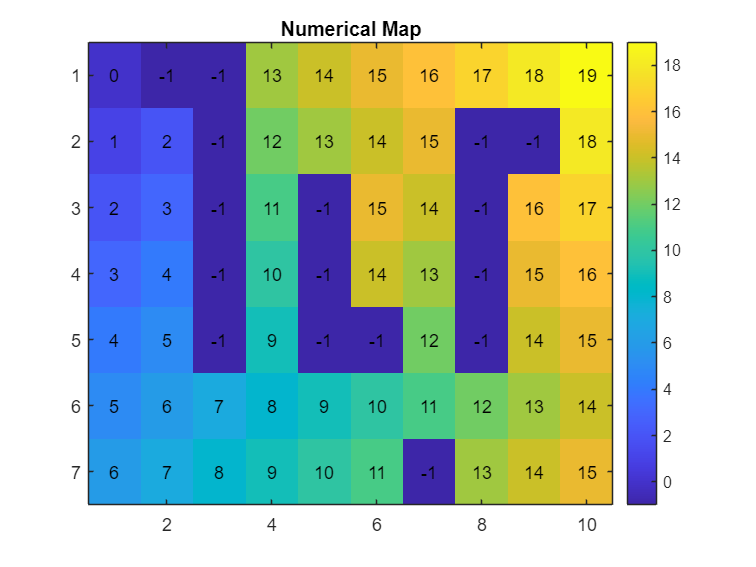


imagesc(numerical_map);
colorbar; % Aggiunge una barra dei colori per visualizzare l'associazione tra numeri e colori
title('Numerical Map');

% Aggiungi i numeri sovrapposti al plot
[n_righe, n_colonne] = size(numerical_map);
for i = 1:n_righe
    for j = 1:n_colonne
        text(j, i, num2str(numerical_map(i, j)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
    end
end


[last_r,last_c] = find(map==2);
last=[last_r,last_c];
path=last

path =      1     8


i=0;

while(numerical_map(last(1),last(2))~=0)
    last_value = numerical_map(last(1),last(2));
    up=last+[-1,0];
    right=last+[0,1];
    down=last+[1,0];
    left=last+[0,-1];
    if(up(1)>0 && up(1)<=7 && up(2)>0 && up(2)<=10)
        if(numerical_map(up(1),up(2)) == last_value-1)
            last = up;
        end
    end
    if(right(1)>0 && right(1)<=7 && right(2)>0 && right(2)<=10)
        if(numerical_map(right(1),right(2)) == last_value-1)
            last = right;
        end
    end
    if(down(1)>0 && down(1)<=7 && down(2)>0 && down(2)<=10)
        if(numerical_map(down(1),down(2)) ==last_value-1)
            last= down;
        end
    end
    if(left(1)>0 && left(1)<=7 && left(2)>0 && left(2)<=10)
        if(numerical_map(left(1),left(2)) ==last_value-1)
            last= left;
            i
        end
    end
    path=[path;last];
end

i = 0

i = 0

i = 0

i = 0

i = 0

i = 0

i = 0

path

path =      1     8
     1     7
     1     6
     1     5
     1     4
     2     4
     3     4
     4     4
     5     4
     6     4


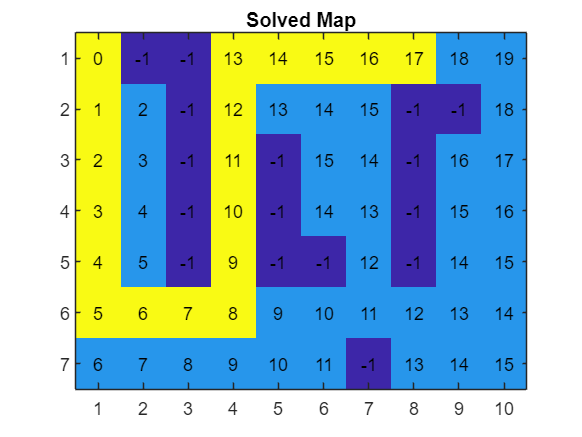

for i=1:length(path(:,1))
    map(path(i,1),path(i,2))=3;
end

imagesc(map);
title('Solved Map');

% Aggiungi i numeri sovrapposti al plot
[n_righe, n_colonne] = size(map);
for i = 1:n_righe
    for j = 1:n_colonne
        text(j, i, num2str(numerical_map(i, j)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
    end
end